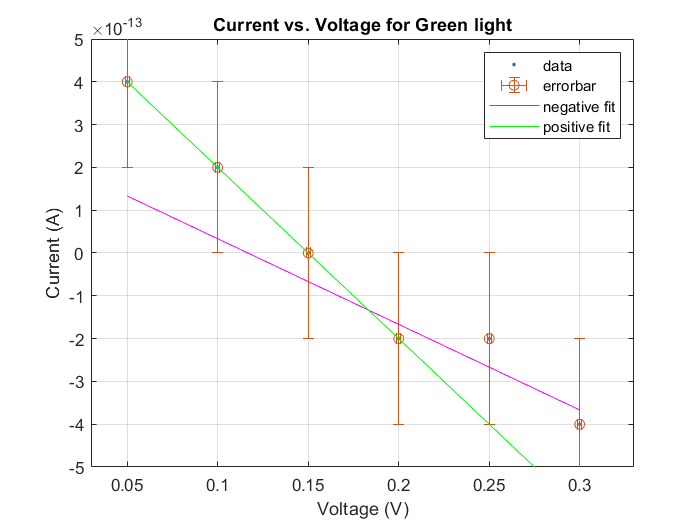

plot(GREENvoltage,GREENcurrent,'.')
hold on

%%CREATING ERRORBARS

xpos=0.001.*[1 1 1 1 1 1];
xneg=xpos;
yneg=(0.2e-12).*[1 1 1 1 1 1];
ypos=yneg;
errorbar(GREENvoltage,GREENcurrent,yneg,ypos,xneg,xpos,'o')



%% NEGATIVE DATA
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =      -2.000e-12  \mp 7.335e-12
  %     p2 =   2.333e-13 \mp 18.584e-13
%Goodness of fit:
 % SSE: 6.667e-27
 % R-square: 0.75
  %Adjusted R-square: 0.5
  %RMSE: 8.165e-14
 p1 =      -2e-12;
 p2 =   2.333e-13;
 f=p1.*GREENvoltage+p2;
 plot(GREENvoltage,f,'m')
 
%% POSITIVE DATA
 %Linear model Poly1:
 %    f(x) = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =      -4.000e-12  0.001e-12
  %     p4 =       6.000e-13  0.001e-13
%Goodness of fit:
 % SSE: 1.682e-55
  %R-square: 1
  %Adjusted R-square: 1
  %RMSE: 4.102e-28
  p3 =      -4e-12 ;
   p4 =       6e-13 ;
   g=p3.*GREENvoltage+p4;
   plot(GREENvoltage,g,'g')
   grid on
   
   
 %%NAMING THE GRAPH  
   xlim([0.03 0.330])
ylim([-0.000000000000500 0.000000000000500])
legend({'data','errorbar','negative fit','positive fit'})
title('Current vs. Voltage for Green light')
xlabel('Voltage (V)')
ylabel('Current (A)')